% Define suspension system equation

% Define specified parameters
c = 1.5*10^3; 
k = 1.5*10^4;
m = 3.6*10^3;

y0 = 0.3;

% Define calculated values
n = c/(2*m);
hpk = k/m;
com = c^2 / (4*m^2);

assert(hpk > com)

rootD = sqrt(hpk - com);

% Define symbol t for use in function
syms t
% Define function
systemFunc(t) = exp(-n*t) * y0 * (cos(rootD*t) + (n/rootD)*sin(rootD*t));




% Plot graph
syms x1;

% define values for x
x1 = 0:0.01:10;

% Pass values of into function and plot
plot(x1,systemFunc(x1),'-b')

% Set x axis to strike throught origin
ax = gca;
ax.XAxisLocation ='origin'

ax =   Axes with properties:

             XLim: [0 10]
             YLim: [-0.3000 0.3000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


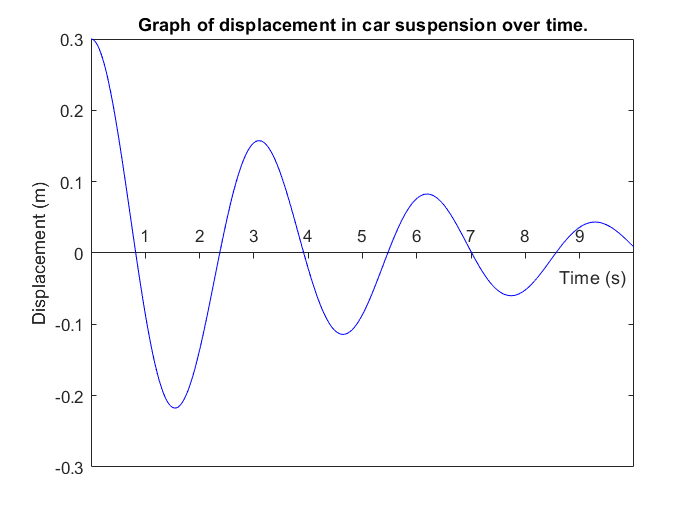


xlabel("Time (s)")
ylabel("Displacement (m)")
title("Graph of displacement in car suspension over time.")

% % Set minimum error value used to find root.
error = 1E-3

error = 1.0000e-03


% Identify the first 3 roots as around 0.5, 2, 3.7
% Calculate roots iteratively using the Newton-Raphson second method.
root1 = double(findRoot(0.5, systemFunc, error))

root1 = 0.8239

root2 = double(findRoot(2, systemFunc, error))

root2 = 2.3710

root3 = double(findRoot(3.7, systemFunc, error))

root3 = 3.9182

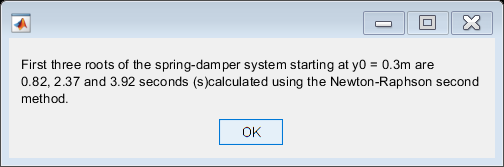


% Print the first 3 roots.
msgbox(sprintf(['First three roots of the spring-damper system starting ' ...
    'at y0 = 0.3m are %2.2f, %2.2f and %2.2f seconds (s)' ...
    'calculated using the Newton-Raphson second method.'],root1,root2,root3))

% Experimental data
time = 2.6:0.05:3.1

time =     2.6000    2.6500    2.7000    2.7500    2.8000    2.8500    2.9000    2.9500    3.0000    3.0500    3.1000


experimentDisp = [0.074, 0.094, 0.106, 0.113, 0.127, 0.145, 0.145, 0.148, 0.154, 0.162, 0.158]

experimentDisp =     0.0740    0.0940    0.1060    0.1130    0.1270    0.1450    0.1450    0.1480    0.1540    0.1620    0.1580


calculatedDisp = double(systemFunc(time))

calculatedDisp =     0.0787    0.0932    0.1064    0.1183    0.1287    0.1376    0.1449    0.1505    0.1545    0.1568    0.1574




e1 = [10, 5, 10, 3, 2]

e1 =     10     5    10     3     2


e2 = [15, 8, 12, 7, 10]

e2 =     15     8    12     7    10



[eR, ee] = calc_md_and_standard_error(e1,e2)

meanY = 6

N = 5

totalSumSquares = 138

residualSumSquares = 58

R = 2.3793

e = 4.6476

eR = 2.3793

ee = 4.6476

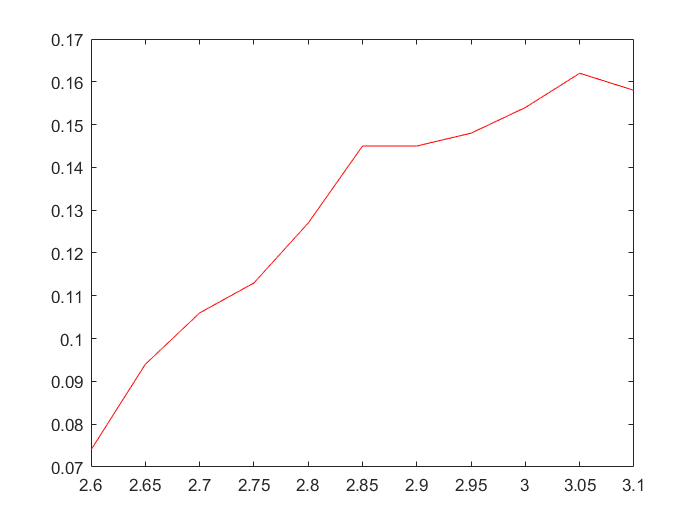


figure

plot(time,experimentDisp,'-r')

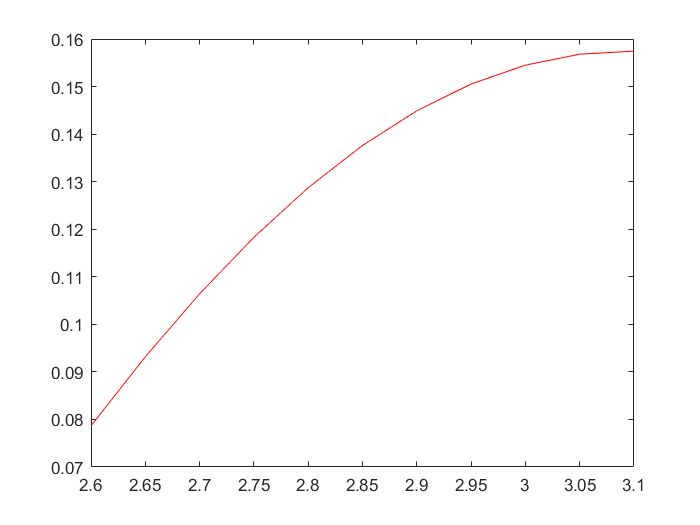


plot(time,calculatedDisp,'-r')


x2 = [0,1,2,3,4,5]

x2 =      0     1     2     3     4     5


x3 = [0,2,3,3,4,5]

x3 =      0     2     3     3     4     5



r = calc_md(x2,x3)

meanX = 2.5000

N = 6

ssXX = 17.5000

ssXY = 15.5000

ssYY = 14.8333

R = 0.9255

r = 0.9255

[R,e] = calc_md_and_standard_error(experimentDisp,calculatedDisp)

meanY = 0.1296

N = 11

totalSumSquares = 0.0075

residualSumSquares = 0.0085

R = 0.8815

e = 0.0000 + 1.4142i

R = 0.8815

e = 0.0000 + 1.4142i

function [R,e] = calc_md_and_standard_error(y,g)
    assert(length(y) == length(g))
    
    meanY = mean(y)
    N = length(y)
    
    totalSumSquares = sum((g - meanY).^2)
    residualSumSquares =sum((y - meanY).^2)

%     total_sum_of_squares = sum((y - mean_y).^2)
%     residual_sum_of_squares =sum((y - g).^2)

    R = (totalSumSquares/residualSumSquares)     
    
    e = sqrt( sum((y-g).^2 )/ N-2 )

end
    
function R = calc_md(x,y)
    assert(length(x) == length(y))
    
    meanX = mean(x)
    N = length(y)
     
    ssXX = sum(x.^2) - 1/N* (sum(x))^2
    ssXY = sum(x.*y) - 1/N * (sum(x)*sum(y))
    ssYY = sum(y.^2) - 1/N * (sum(y))^2

    R = (ssXY / sqrt(ssXX*ssYY))^2
   

end
function [a,b] = linear_regression(x,y)
    assert(length(x) == length(y))
    
    x_sum = sum(x)
    y_sum = sum(y)
    xy_sum = sum(x.*y)
    x_square_sum = sum(x.^2)
    N = length(x)
    
    denom = N*x_square_sum - x_sum^2
    
    a = (y_sum*x_square_sum - xy_sum*x_sum) / denom
    b = (N*xy_sum - y_sum*x_sum) / denom 

end


function x = findRoot(x0,func,error)
% Iteratively calculate the root to within a certain error using 
% the newton rhapson formula.

% Check required error is greater than 0
    assert(error > 0)
    
%     Find the first estimate for x
    x = newtonRhapson_2(x0,func);
%     Use the new value for x to find the height at that point
    y = func(x);
    
%     While height is not within the margin for error then loop
    while abs(y) > error
%         Calculate a new estimate for x
        x = double(newtonRhapson_2(x,func));
%         Calculate the height at thtat point
        y = double(func(x));
    end
end

function x = newtonRhapson_2(x0,func)
% mplementation of Newton Rhapson's second equation.
% Note it would be more efficicient to calculate the dervatives once and 
% inline this function into findRoot, however I believe this is easier to
% read.

% Calulate the first derivative of the given function
    der_func = diff(func);
% Calculate the second dervative of the given function
    sec_der_func  = diff(func,2);
    
% Calculate the slope when x = x0
    slope = der_func(x0);
% Calculate the derivative of the slope when x = x0
    der_slope = sec_der_func(x0);
    
    x = x0 + (der_slope/(2*slope) - slope/func(x0))^-1;
end